clear all; close all

legend_names = {'load';'motor'};

%data analysis
fs = 4000; %[Hz]
stepsize = 1/fs; %[s]

%loading experiment data
load("nieuwe_setup_gain_0.2.mat")
u_l = u; d_l = d;
load("nieuwe_setup_gain_0.1_motor_side.mat")
u_m = measurement(:,1); d_m = measurement(:,2); %writing data to unique names
clear u d %clearing unused data

%removing useless data 
N_trash = 1000; 
u_l = u_l(N_trash:end); d_l = d_l(N_trash:end);
u_m = u_m(N_trash:end); d_m = d_m(N_trash:end);

% Plot the measurement
figure(); clf();
stairs(u_l); hold on; stairs(d_l);
xlabel('Time [s]'); ylabel('Signal [volt,rad]');
hold off

% Plot the measurement
figure(); clf();
stairs(u_m); hold on; stairs(d_m);
xlabel('Time [s]'); ylabel('Signal [volt,rad]');
hold off

%window settings
min_freq = 0.1; %[Hz/s] lowest desired sampling frequency
windowsize = 1/min_freq; %[s] window size in seconds
nfft = round(windowsize/stepsize); %window size in data points 
n_overlap = round(nfft/5);

%Tf estimate
[S_l, F_l] = tfestimate(d_l,u_l,hann(nfft),n_overlap,nfft,fs); %cross spectral power density
[S_m, F_m] = tfestimate(d_m,u_m,hann(nfft),n_overlap,nfft,fs); %cross spectral power density

%{
figure()
semilogx(F,mag2db(abs(S)))
title("sensitivity magnitude")
grid on; hold off

figure()
semilogx(F,angle(S)/pi*180)
title('sensitivity phase')
grid on; hold off
%}

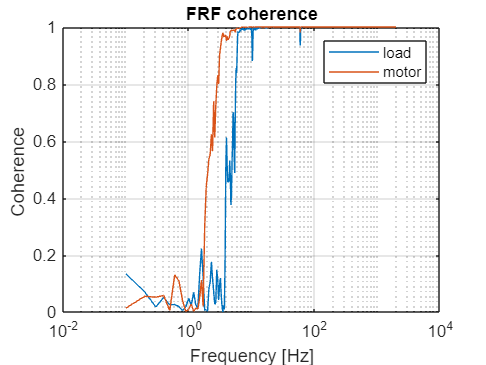

fig = figure();
[cxy, f] = mscohere(d_l,u_l,hann(nfft),n_overlap,nfft,fs);
semilogx(f, cxy)
hold on
[cxy, f] = mscohere(d_m,u_m,hann(nfft),n_overlap,nfft,fs);
semilogx(f,cxy)
title('FRF coherence')
xlabel('Frequency [Hz]')
ylabel('Coherence ')
legend(legend_names)
grid on; hold off

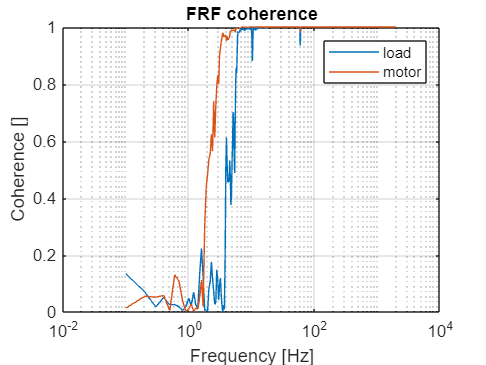


saveas(fig,'system_coherence.png')


%plotting open loop transfer function
k_l = 0.2;
k_m = 0.1;
H_l = (1 / k_l) * (1./S_l- 1);
H_m = (1 / k_m) * (1./S_m - 1);

f = figure()

f =   Figure (8) with properties:

      Number: 8
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [488 242 560 420]
       Units: 'pixels'

  Show all properties


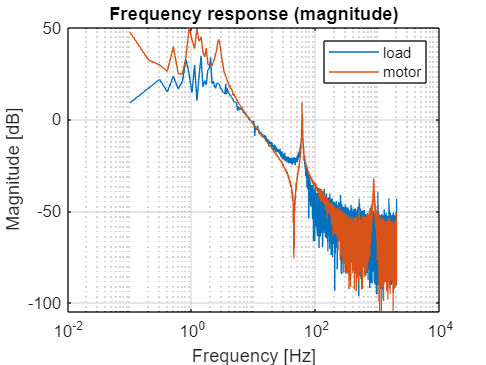

semilogx(F_l,mag2db(abs(H_l)))
hold on
semilogx(F_m,mag2db(abs(H_m)))
title('Frequency response (magnitude)')
xlabel("Frequency [Hz]")
ylabel("Magnitude [dB]")
legend(legend_names)
grid on; hold off
saveas(f,'system_magnitude_response.png')


f = figure()

f =   Figure (9) with properties:

      Number: 9
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [488 242 560 420]
       Units: 'pixels'

  Show all properties


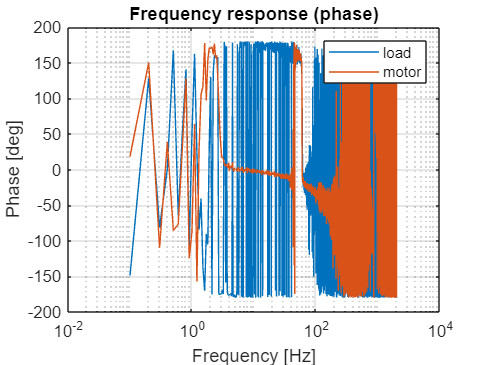

semilogx(F_l,angle(H_l)/pi*180)
hold on 
semilogx(F_m,angle(H_m)/pi*180)
title('Frequency response (phase)')
xlabel('Frequency [Hz]')
ylabel('Phase [deg]')
legend(legend_names)
grid on; hold off
saveas(f,'System_phase_response.png')

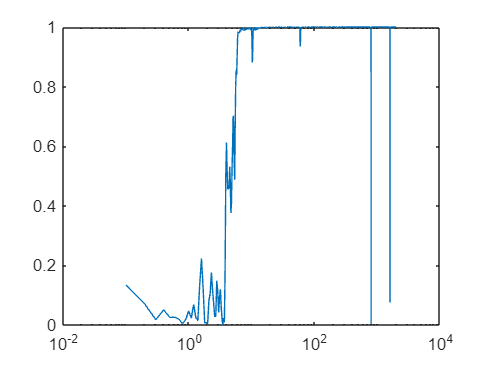

[cxy, f] = mscohere(d_l,smooth(u_l),hann(nfft),n_overlap,nfft,fs);
semilogx(f,cxy)


Sdd = pwelch(d_m,hann(nfft),n_overlap,nfft); %spectral power disturbance
Suu = pwelch(u_m,hann(nfft),n_overlap,nfft); %spectral power input
C_m = 1./abs(H_m).^2 .*Suu./Sdd

C_m = 1.0e+10 *

    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


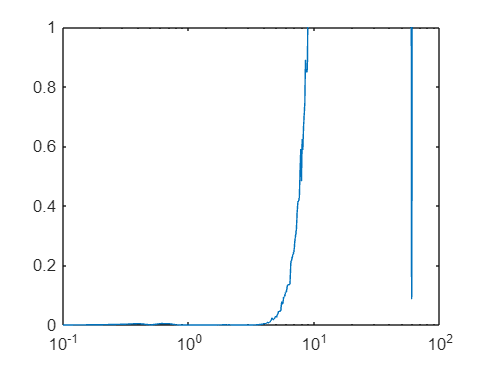

semilogx(F_m,C_m)
ylim([0 1])